# Graph Classification using GCN

v0.1

TL;DR : **Graph Classification proof-of-concept example**

This simple example demonstrates a custom implementation of GCN (graph Convolution network) for graph level classification task. We have used PROTEINS dataset here (or rather a subset of it)

Dataset ref: https://ls11-www.cs.tu-dortmund.de/staff/morris/graphkerneldatasets

Graph Classification is a more non-trivial task compared to node-classification as the input graph could have different sizes. This issues is mitigated to some extent by padding

Requirement: MATLAB R2021a+

## Loading in Data

First things first, let us load in our PROTIENS dataset. This loads it adjaceny matrix ('adj'), the node-features ('feat'), the lables ('label') and unmodified adjaceny matrices for plotting ('old_adj')

%[adj,feat,label,old_adj]=protein_load();
load data.mat
rng(42,'twister');
%Test set creation and shuffling
shuff = randperm(length(adj));
test_set=shuff(end-200:end);
shuff = shuff(1:end-200);

I am only using a sub-set of PROTEINS dataset. A challenging issue for graph classification is that that the size of graphs can vary. To counter this I have used padding. The network takes in graphs of fixed size(50). All graphs that have nodes < 50 have been padded with 0. This results in arond 871 graphs. I set 200 of these aside for test. This pre-processed data is stored in data.mat file

### About the dataset

PROTEINS is a dataset of proteins that are classified as enzymes or non-enzymes. Nodes represent the amino acids and two nodes are connected by an edge if they are less than 6 Angstroms apart. The node features are 1 dimensional (atmoic weights).

**Advanced Aside**: The protein_load() function can be modified to specify the number of graph and their sizes. One alternate is to have a network with multiple different heads to process graphs of different sizes with pooling. The protein_load function also pre-processes the adjacency matrix according to graph convolution operation. Check it out for more advanced modifications.

## Visualization

Let us try to visualize an entry. We plot the 3rd protein example using its adjacency matrix

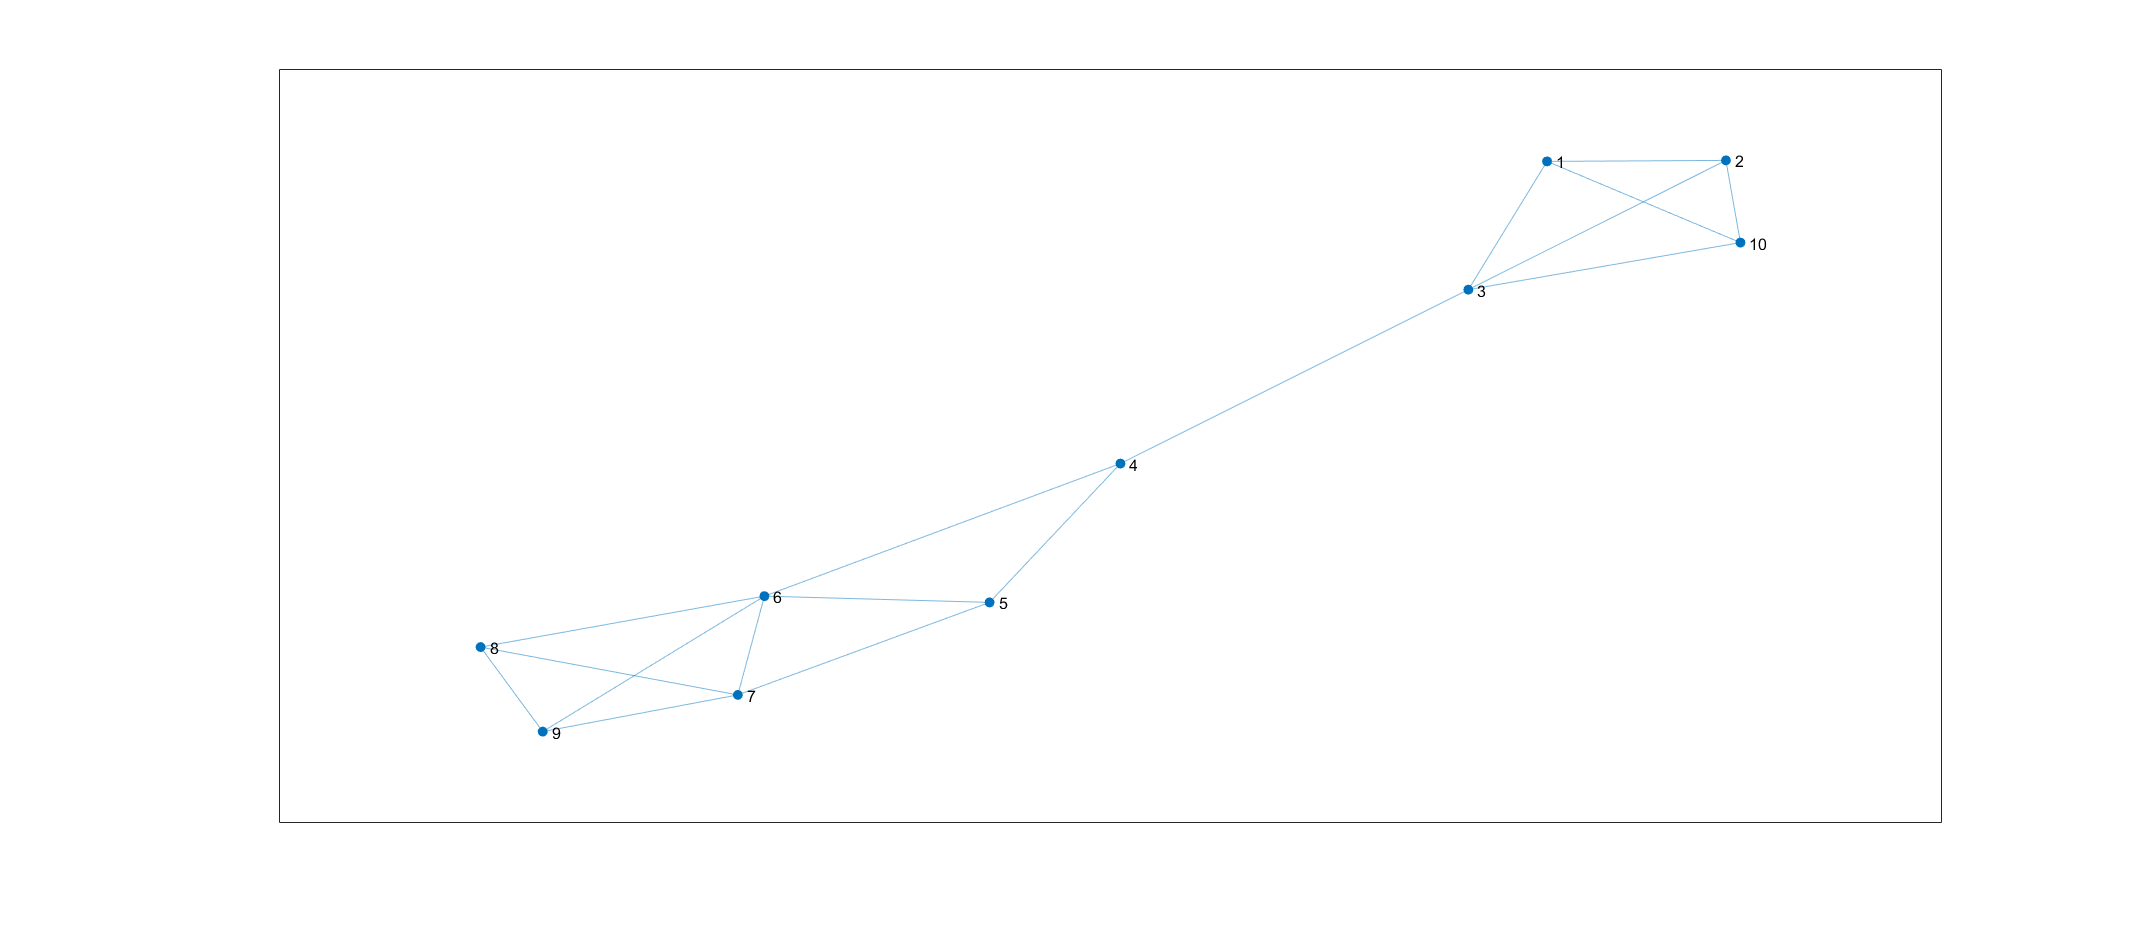

GNN_viz(3,old_adj)

## Designing the Network

We will create a simple classification network with two GCN layers (two accumators) and a fully connected layer. 

GCN = Graph Conv layer (needs weight size as input)

GNN_interface = This layer is needed at the end of GCN layers to provide interface for rest of the network.

Network architecture

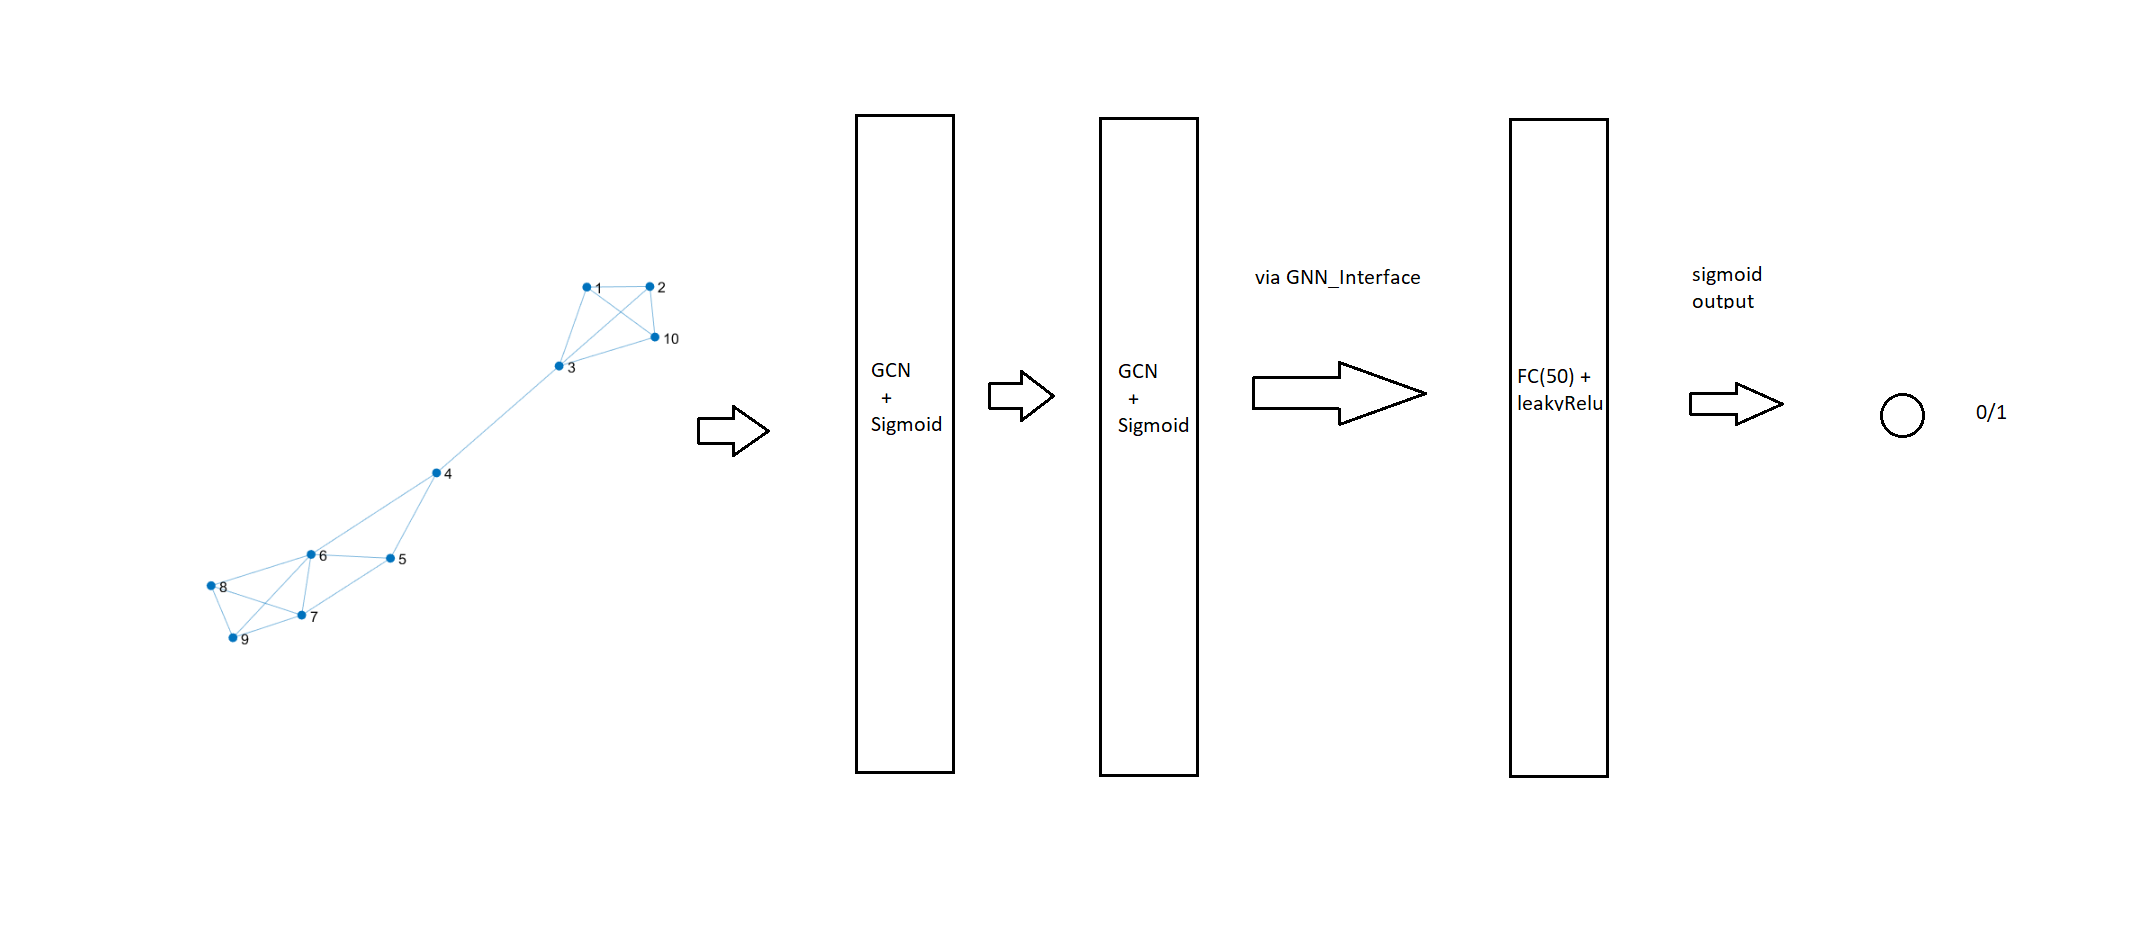

imshow('arch.png')

Input +> GCN -> GCN -> GNN_interface -> FC(30) -> FC(1)

layer1 = GCN([1,2],'firstGCN');
layer2 = GCN([2,2],'secondGCN');
layer3 = GCN([2,1],'thirdGCN');
layer4 = GNN_interface(50,'final');
layer5 = fullyConnectedLayer(30,'Name','fc1','WeightsInitializer','glorot');
layer6 = fullyConnectedLayer(1,'Name','fc2','WeightsInitializer','glorot');
act1 = leakyReluLayer(0.1,'Name','lr');
act2 = sigmoidLayer('Name','ss');
my_net = [layer1,layer2,layer3,layer4,layer5,act1,layer6,act2];

Now we connect the layers and create a 'dlnetwork' object

Adja = dlarray(ones(50),'CU');
feata = dlarray(ones([50,1]),'C');
lgraph = layerGraph();
lgraph = addLayers(lgraph,my_net);
lgraph = connectLayers(lgraph,"firstGCN/out2","secondGCN/in2");
lgraph = connectLayers(lgraph,"secondGCN/out2","thirdGCN/in2");
lgraph = connectLayers(lgraph,"thirdGCN/out2","final/in2");
%create a dlnetwork with sample input
my_net = dlnetwork(lgraph,Adja,feata);


Lets plot out our graph

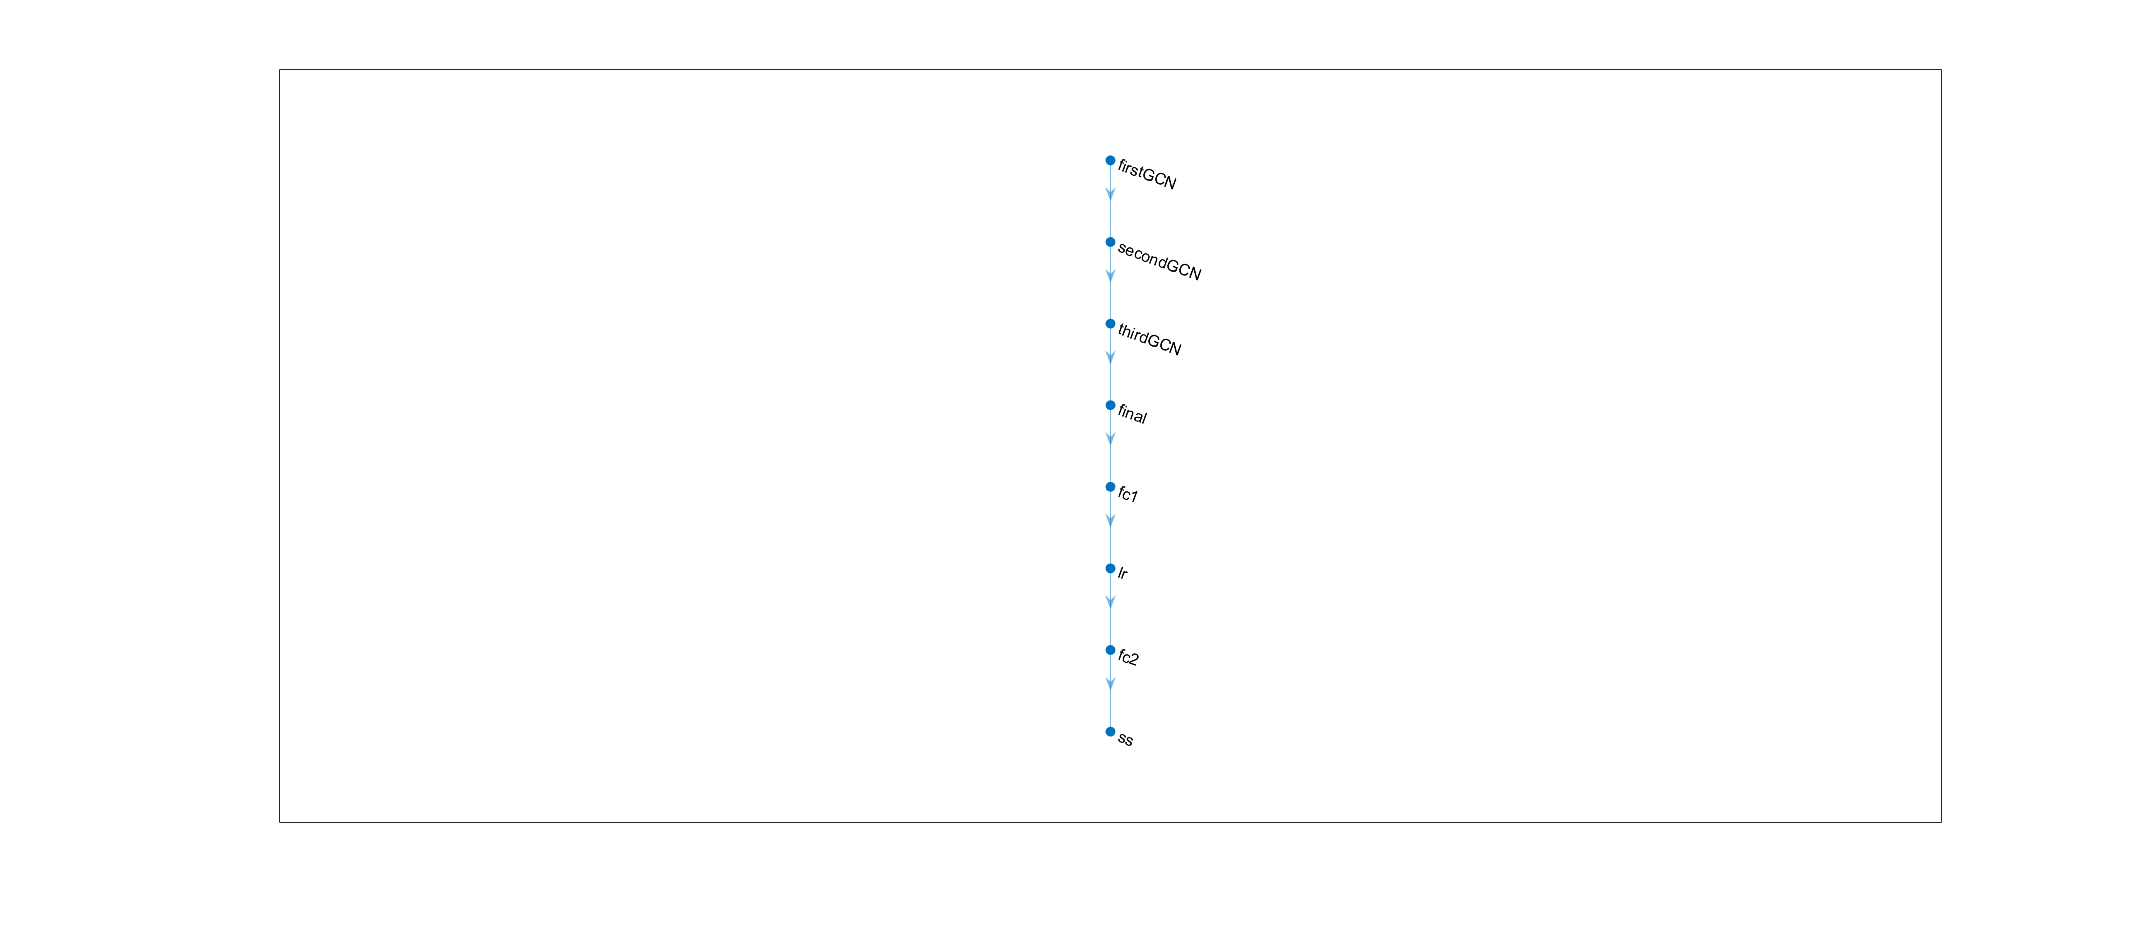

plot(lgraph)

## **Network Training**

We first set the hyperparameters for training out network

train_len = length(shuff)

train_len = 671

epochs = 30;
learnRate = 0.01;
momentum = 0.90;
vel = [];

Let the training begin,

% very very hacky
for j=1:epochs
losstot=0;
for i=1:train_len
    var1=dlarray(adj{shuff(i)},'CU');
    var2=dlarray(feat{shuff(i)},'C');
    var3=dlarray(label(shuff(i))-1,'CB');
    [grad,los]=dlfeval(@GNN_Gradients,my_net,var1,var2,var3);
    losstot = losstot + los;
    [my_net,vel] = sgdmupdate(my_net,grad,vel,learnRate,momentum);
end   
disp(['Average error for epoch ',num2str(j),' is : ',num2str(losstot/train_len)])
end

Average error for epoch 1 is : 0.69778
Average error for epoch 2 is : 0.69367
Average error for epoch 3 is : 0.68079
Average error for epoch 4 is : 0.62561
Average error for epoch 5 is : 0.60435
Average error for epoch 6 is : 0.59829
Average error for epoch 7 is : 0.5954
Average error for epoch 8 is : 0.59349
Average error for epoch 9 is : 0.59195
Average error for epoch 10 is : 0.59067
Average error for epoch 11 is : 0.59025
Average error for epoch 12 is : 0.5893
Average error for epoch 13 is : 0.58862
Average error for epoch 14 is : 0.5882
Average error for epoch 15 is : 0.58777
Average error for epoch 16 is : 0.5871
Average error for epoch 17 is : 0.5866
Average error for epoch 18 is : 0.5855
Average error for epoch 19 is : 0.58507
Average error for epoch 20 is : 0.58432
Average error for epoch 21 is : 0.58428
Average error for epoch 22 is : 0.58413
Average error for epoch 23 is : 0.58458
Average error for epoch 24 is : 0.58299
Average error for epoch 25 is : 0.58313
Average error f

Finally we test the accuracy of the network on the 201 graphs we set aside for testing

test_len = 201

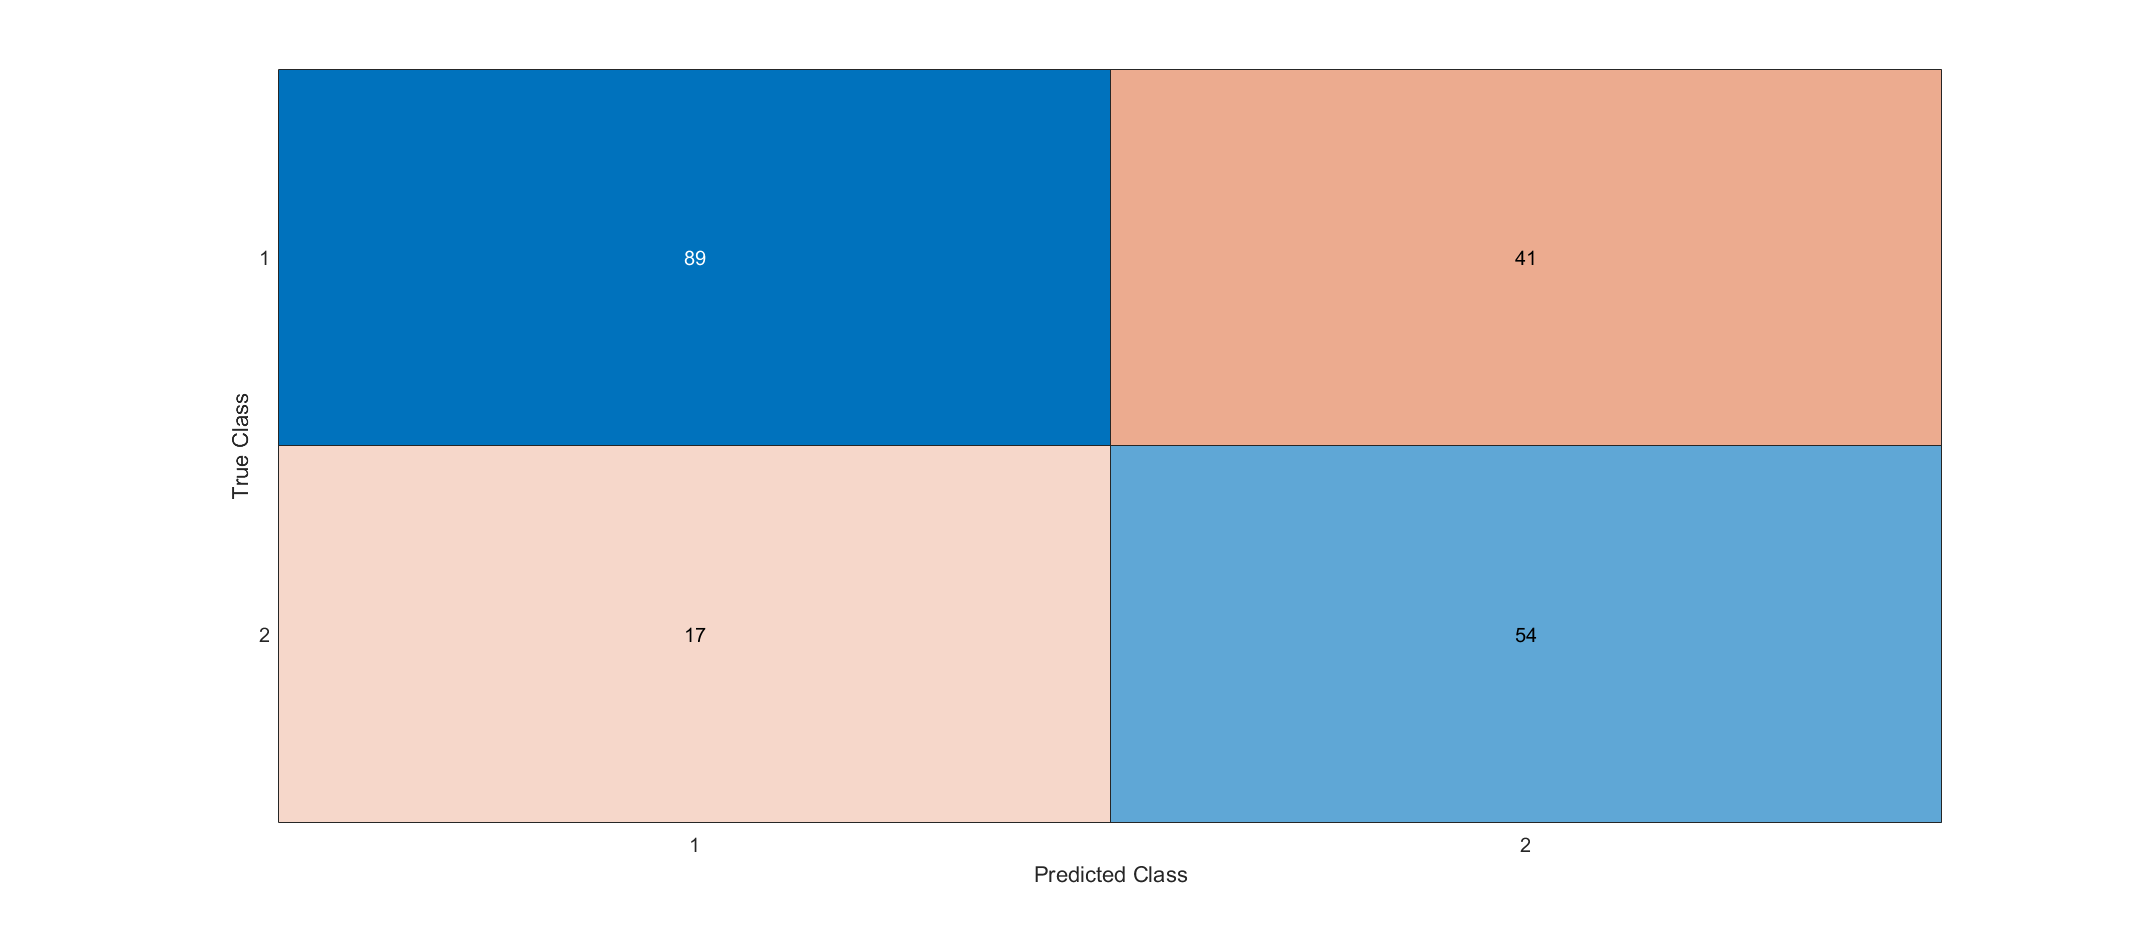

ans = 71.1443

GNN_test(my_net,adj,feat,label,test_set)

**Accuracy of 71-72 is not great (specially for the first class)! but its not bad either considering SOTA is 84% on PROTEINS** and our network was the most basic one and trained only on a subset of graphs. Some future things that I intend to try to increase the accuracy:

1) Graph Batching: We did not have any batching whatsover.

2) Graph Pooling : Pooling operations would be useful in graph classification tasks.

3) Optimizations and network tuning

4) Add gpuArray support

5)Other datasets